# Multi-Period Distributed Optimal Power Flow

## One time-step Optimization at a time.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-AlgoTesting", filesep) )
    addpath(genpath('functions\'))
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = false;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 1;
macroItrMax = 10; % Max no. of permissible iterations for optimizing an area

if numAreas == 1
    copf = true;
else
    copf = false;
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

delta_t = 0.25; % 15 minutes = 0.25 hours
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')

lambdaVals = 1

loadVals = lambdaVals*3

loadVals = 3

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)
pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

pvCoeffVals = 1


% Stopping Criterion:
tol = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
else
    error("Objective Function NOT recognized.")
end

plottingSpecificationFolder = strcat("plottingSpecifications", filesep);

tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};
for i = 1:length(tableNames)
    tableType = tableNames{i};
    tableName = strcat(tableType, "Table");
    table = readtable(fullfile(plottingSpecificationFolder, strcat(tableName, ".csv")));
    eval([tableType, ' = table2struct(table, "ToScalar", true);']);
end

timePeriods = transpose(1:T);
[PLosses, QLosses, PSubs, QSubs, solutionTimes] = deal( zeros(T, 1) );
[P12s, Q12s, V1s, PSaves] = deal( zeros(T, numAreas));
[P_ij, Q_ij, S_ij, l_ij, v_j, qD_j, B_j_pu, B_j, Pc_j_pu, Pc_j, Pd_j_pu, Pd_j, qB_j] = deal( zeros(T, numAreas, N));

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
N_Areas = zeros(numAreas, 1);
m_Areas = zeros(numAreas, 1);
nDER_Areas = zeros(numAreas, 1);
nBatt_Areas = zeros(numAreas, 1);

#### Start with the algorithm

for t = 1:T
    if logging && verbose
        error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
    elseif logging && ~verbose
        fileOpenedFlag = true;
        if t == 1
            fid = fopen(saveLocationFilename, 'w');
        else
            fid = fopen(saveLocationFilename, 'a');
        end
    elseif ~logging
        logging = verbose;
        fid = 1;
    end
    
    if t == 1
        myfprintf(true, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
    "will be run.\n", T, delta_t*60, delta_t*T);
    end

    myfprintf(true, "********Running OPF for the system for Time Period = %d.********\n", t); %always true
    keepRunningIterations = true;
    macroItr = 1;
    time_dist = zeros(macroItrMax, numAreas);
    macroIterationPLosses = zeros(macroItrMax, numAreas);
    macroIterationQLosses = zeros(macroItrMax, numAreas);
    macroIterationPSaves = zeros(macroItrMax, numAreas);
    % ResidualMax = zeros(macroItrMax, 1);
    v2_parent = 1.03^2*ones(numAreas, 1);
    maxResidual_vs_macroItr = zeros(macroItrMax, 1);

    Se_iter = zeros(macroItrMax, numAreas);
    V_iter = zeros(macroItrMax, N, numUniqueParents);
    S_allRelationships = CBTable.S_childArea;
    S_parent = zeros(numAreas, 1);
    S_Areas = zeros(N, numAreas);
    v2_Areas = zeros(N, numAreas);
    
    while keepRunningIterations
        for Area = 1:numAreas
        % for Area = 1
        % for Area = 2

            myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr, Area);

            v2_parent_Area = v2_parent(Area)
            S_childAreas = S_allRelationships(CBTable.parentArea == Area)
    
            isLeaf_Area = isLeaf(Area);
            isRoot_Area = isRoot(Area);
            numChildAreas_Area = numChildAreas(Area);
            
            B0Vals_pu_Area = B_j_pu(t, Area, :);
    
            [xVals_Area, B0Vals_pu_Area, macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, ...
                macroItr, time_dist, N_Area, m_Area, nDER_Area, nBatt_Area, busDataTable_Area, branchDataTable_Area] = ...
                ...
                NL_OPF_dist(v2_parent_Area, S_childAreas, B0Vals_pu_Area, ...
                Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, ...
                numAreas, ...
                macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, lambdaVals, pvCoeffVals, time_dist, t, macroItr,  ...
                CBTable, T, 'verbose', verbose, 'saveToFile', true, 'logging', logging);
            
            N_Areas(Area) = N_Area;
            m_Areas(Area) = m_Area;
            nDER_Areas(Area) = nDER_Area;
            nBatt_Areas(Area) = nBatt_Area;

            numVarsFull = [m_Area, m_Area, m_Area, N_Area, nDER_Area, nBatt_Area, nBatt_Area, nBatt_Area, nBatt_Area];
            ranges_Full = generateRangesFromValues(numVarsFull);

            indices_P = ranges_Full{1};
            indices_Q = ranges_Full{2};
            indices_l = ranges_Full{3};
            indices_vAll = ranges_Full{4};
            indices_v = indices_vAll(2:end);
            indices_qD = ranges_Full{5};
            indices_B = ranges_Full{6};
            indices_Pc = ranges_Full{7};
            indices_Pd = ranges_Full{8};
            indices_qB = ranges_Full{9};
            
            P_Area = xVals_Area(indices_P); %m_Areax1
            Q_Area = xVals_Area(indices_Q); %m_Areax1
            S_Area = complex(P_Area, Q_Area); %m_Areax1
            l_Area = xVals_Area(indices_l);
            vFull_Area = xVals_Area(indices_vAll); %N_Areax1
            v2_Area = vFull_Area;
            qD_Area = xVals_Area(indices_qD);
            B_Area = xVals_Area(indices_B);
            Pd_Area = xVals_Area(indices_Pd);
            Pc_Area = xVals_Area(indices_Pc);
            qB_Area = xVals_Area(indices_qB);

            P_ij(t, Area, 1:m_Area) = P_Area;
            Q_ij(t, Area, 1:m_Area) = Q_Area; %m_Areax1
            S_ij(t, Area, 1:m_Area) = complex(P_Area, Q_Area); %m_Areax1
            l_ij(t, Area, 1:m_Area) = l_Area;
            v_j(t, Area, 1:N_Area) = vFull_Area;
            qD_j(t, Area, 1:nDER_Area) = qD_Area;
            B_j_pu(t, Area, 1:nBatt_Area) = B0Vals_pu_Area;

            P_der_BusesWithBatts = busDataTable_Area(busDataTable_Area.P_der ~= 0, :).P_der;
            B_j(t, Area, 1:nBatt_Area) = 100*B0Vals_pu_Area./(chargeToPowerRatio * P_der_BusesWithBatts);
            B_j_pu(t+1, Area, 1:nBatt_Area) = B_Area;
            B_j(t+1, Area, 1:nBatt_Area) = 100*B_Area./(chargeToPowerRatio * P_der_BusesWithBatts);
            Pc_j_pu(t, Area, 1:nBatt_Area) = Pc_Area;
            Pc_j(t, Area, 1:nBatt_Area) = Pc_Area * kVA_B;
            Pd_j_pu(t, Area, 1:nBatt_Area) = Pd_Area;
            Pd_j(t, Area, 1:nBatt_Area) = Pd_Area * kVA_B;
            qB_j(t, Area, 1:nBatt_Area) = qB_Area;

            
            S_parent(Area) = S_Area(1);
            
            v2_Areas(1:N_Area, Area) = vFull_Area;
            S_Areas(1:m_Area, Area) = S_Area;   % Storing all the S flow of the Area
            % keyboard
        end
        myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr);

        
        if ~copf
            for relationshipNum = 1 : numRelationships
        
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);
    
                parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
                S12_fromParent = S_Areas(parentAreaConnectingBus - 1, parAr)
                S12_intoChild = S_parent(chAr)
        
                delta_S12 = S12_fromParent - S12_intoChild
        
                v2_parentSide = v2_Areas(parentAreaConnectingBus, parAr)
                v2_childSide = v2_parent(chAr)
        
                delta_v2 = v2_parentSide - v2_childSide
        
                Residual_Area = [delta_S12; delta_v2]
                [currentMaxResidual, lin_idx] = max(abs(Residual_Area))
                row = lin_idx;
                myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr, currentMaxResidual, row);
    
                if currentMaxResidual > maxResidual_vs_macroItr(macroItr+1)
                    maxResidual_vs_macroItr(macroItr+1) = currentMaxResidual;
                    myfprintf(true, "It is even bigger than the previous biggest residual.\n");
                end
                % if max(abs(Residual_Area)) > ResidualMax(macroItr+1)
                %     ResidualMax(macroItr+1) = max(abs(Residual_Area))
                % end
        
            end
            myfprintf(true, "Macro-iteration %d: Communication between all connected areas completed.\n", macroItr);
    
            if macroItr >= macroItrMax
                % keepRunningIterations = false;
                error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
        
            elseif maxResidual_vs_macroItr(macroItr+1) < tol
                myfprintf(true, "Time Period = %d, Converged in %d macro-iterations!\n", t, macroItr);
                keepRunningIterations = false;
                maxResidual_vs_macroItr = maxResidual_vs_macroItr(1:macroItr);
        
            else
                myfprintf(true, "Time Period = %d, Still yet to converge after %d macro-iterations, continuing.\n", t, macroItr)
                %Communication-
                 myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                    "let's exchange boundary variables.\n")

                for relationshipNum = 1:numRelationships
                    parAr = CBTable.parentArea(relationshipNum);
                    chAr = CBTable.childArea(relationshipNum);
                    myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);
    
                    busParTo = CBTable.conBus_parentAreaTo(relationshipNum);
                    V_iter(macroItr+1, busParTo, parAr) = v2_Areas(busParTo, parAr) ;
                    Se_iter(macroItr+1,chAr) = S_parent(chAr);
        
                    if macroItr > 2
                        myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr)
                        v2_parent(chAr) = a(2)*V_iter(macroItr-1, busParTo, parAr)+...
                            a(1)*V_iter(macroItr, busParTo, parAr)+...
                            (1-sum(a))*v2_Areas(busParTo, parAr);
                        disp(v2_parent(chAr))
                        
                        myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr)
                        S_allRelationships(relationshipNum) = a(2)*Se_iter(macroItr-1, chAr)+...
                            a(1)*Se_iter(macroItr, chAr)+...
                            (1-sum(a))*S_parent(chAr);
                        disp(S_allRelationships(relationshipNum))
                    else
                        myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr)
                        v2_parent(chAr) = v2_Areas(busParTo, parAr)
                        myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr)
                        S_allRelationships(relationshipNum) = S_parent(chAr)
        
                    end
        
                end
        
                macroItr = macroItr + 1;
        
            end

        else
            keepRunningIterations = false;
            myfprintf(true, "Centralized MPOPF for %d Horizons ended.\n", T);

        end

        S12 = transpose(S_Areas(1, :));
        P12s(t, :) = kVA_B*real(S12);
        Q12s(t, :) = kVA_B*imag(S12);
        V1s(t, :) = sqrt(transpose(v2_Areas(1, :)));
        PSaves(t, :) = macroIterationPSaves(macroItr, :);
    
    end
    
    N_ParentArea_Max = max(N_Areas(uniqueParents));
    Se_iter = Se_iter(1:macroItr, :);
    V_iter = V_iter(1:macroItr, 1:N_ParentArea_Max, uniqueParents);
    
    macroIterationPLosses = macroIterationPLosses(1:macroItr, :);
    macroIterationQLosses = macroIterationQLosses(1:macroItr, :);
    time_dist = time_dist(1:macroItr, :);
    
    PLosses(t) = kVA_B * sum(macroIterationPLosses(macroItr, :)); %sum over each row
    QLosses(t) = kVA_B * sum(macroIterationQLosses(macroItr, :));
    PSubs(t) = P12s(t, 1);
    QSubs(t) = Q12s(t, 1);
    solutionTimes(t) = sum(time_dist(macroItr, :));

    postProcessResults(T, N, numAreas, N_Areas, isRoot, v2_Areas, actualBusNums, ...
        macroIterationPLosses, t, macroItr, time_dist, kVA_B, displaySimulationResultPlots, ...
        maxResidual_vs_macroItr, saveSimulationResultPlots, systemName, S_Areas, start, generateTextFilesForResults);

end

A total of 1 time-periods (of 15 minutes each, so 0.25 hours in total) will be run.


********Running OPF for the system for Time Period = 1.********


Macro-iteration 1: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =      0
     0


Macro-iteration 1: Running OPF for Area 2.


v2_parent_Area = 1.0609

S_childAreas = 0

Macro-iteration 1: Running OPF for Area 3.


v2_parent_Area = 1.0609


S_childAreas =

  0×1 empty double column vector



Macro-iteration 1: Running OPF for Area 4.


v2_parent_Area = 1.0609


S_childAreas =

  0×1 empty double column vector



Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 2.7449e-26 - 7.8643e-26i

S12_intoChild = 0.0551 + 0.0150i

delta_S12 = -0.0551 - 0.0150i

v2_parentSide = 1.0589

v2_childSide = 1.0609

delta_v2 = -0.0020

Residual_Area =   -0.0551 - 0.0150i
  -0.0020 + 0.0000i


currentMaxResidual = 0.0571

lin_idx = 1

Macro-iteration 1: Current Biggest Residual is 5.707616e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = -3.8841e-28 - 1.3862e-26i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = -0.0756 - 0.0400i

v2_parentSide = 1.0582

v2_childSide = 1.0609

delta_v2 = -0.0027

Residual_Area =   -0.0756 - 0.0400i
  -0.0027 + 0.0000i


currentMaxResidual = 0.0855

lin_idx = 1

Macro-iteration 1: Current Biggest Residual is 8.548843e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 4.9611e-26 + 5.8466e-26i

S12_intoChild = 0.1432 - 0.0365i

delta_S12 = -0.1432 + 0.0365i

v2_parentSide = 1.0582

v2_childSide = 1.0609

delta_v2 = -0.0027

Residual_Area =   -0.1432 + 0.0365i
  -0.0027 + 0.0000i


currentMaxResidual = 0.1477

lin_idx = 1

Macro-iteration 1: Current Biggest Residual is 1.477425e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Communication between all connected areas completed.


Time Period = 1, Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v2_parent =     1.0609
    1.0589
    1.0609
    1.0609


***Macro-iteration 1 Communication Power:****


S_allRelationships =    0.0551 + 0.0150i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v2_parent =     1.0609
    1.0589
    1.0582
    1.0609


***Macro-iteration 1 Communication Power:****


S_allRelationships =    0.0551 + 0.0150i
   0.0756 + 0.0400i
   0.0000 + 0.0000i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v2_parent =     1.0609
    1.0589
    1.0582
    1.0582


***Macro-iteration 1 Communication Power:****


S_allRelationships =    0.0551 + 0.0150i
   0.0756 + 0.0400i
   0.1432 - 0.0365i


Macro-iteration 2: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =    0.0551 + 0.0150i
   0.0756 + 0.0400i


Macro-iteration 2: Running OPF for Area 2.


v2_parent_Area = 1.0589

S_childAreas = 0.1432 - 0.0365i

Macro-iteration 2: Running OPF for Area 3.


v2_parent_Area = 1.0582


S_childAreas =

  0×1 empty double column vector



Macro-iteration 2: Running OPF for Area 4.


v2_parent_Area = 1.0582


S_childAreas =

  0×1 empty double column vector



Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 0.0551 + 0.0150i

S12_intoChild = 0.1988 - 0.0006i

delta_S12 = -0.1437 + 0.0156i

v2_parentSide = 1.0530

v2_childSide = 1.0589

delta_v2 = -0.0059

Residual_Area =   -0.1437 + 0.0156i
  -0.0059 + 0.0000i


currentMaxResidual = 0.1446

lin_idx = 1

Macro-iteration 2: Current Biggest Residual is 1.445811e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = 0.0756 + 0.0400i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = -6.8520e-08 - 2.6465e-07i

v2_parentSide = 1.0497

v2_childSide = 1.0582

delta_v2 = -0.0085

Residual_Area =   -0.0000 - 0.0000i
  -0.0085 + 0.0000i


currentMaxResidual = 0.0085

lin_idx = 2

Macro-iteration 2: Current Biggest Residual is 8.524504e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 0.1432 - 0.0365i

S12_intoChild = 0.1432 - 0.0366i

delta_S12 = -1.3422e-06 + 1.0086e-05i

v2_parentSide = 1.0526

v2_childSide = 1.0582

delta_v2 = -0.0056

Residual_Area =   -0.0000 + 0.0000i
  -0.0056 + 0.0000i


currentMaxResidual = 0.0056

lin_idx = 2

Macro-iteration 2: Current Biggest Residual is 5.590723e-03 at index 2.


Macro-iteration 2: Communication between all connected areas completed.


Time Period = 1, Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v2_parent =     1.0609
    1.0530
    1.0582
    1.0582


***Macro-iteration 2 Communication Power:****


S_allRelationships =    0.1988 - 0.0006i
   0.0756 + 0.0400i
   0.1432 - 0.0365i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v2_parent =     1.0609
    1.0530
    1.0497
    1.0582


***Macro-iteration 2 Communication Power:****


S_allRelationships =    0.1988 - 0.0006i
   0.0756 + 0.0400i
   0.1432 - 0.0365i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v2_parent =     1.0609
    1.0530
    1.0497
    1.0526


***Macro-iteration 2 Communication Power:****


S_allRelationships =    0.1988 - 0.0006i
   0.0756 + 0.0400i
   0.1432 - 0.0366i


Macro-iteration 3: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =    0.1988 - 0.0006i
   0.0756 + 0.0400i


Macro-iteration 3: Running OPF for Area 2.


v2_parent_Area = 1.0530

S_childAreas = 0.1432 - 0.0366i

Macro-iteration 3: Running OPF for Area 3.


v2_parent_Area = 1.0497


S_childAreas =

  0×1 empty double column vector



Macro-iteration 3: Running OPF for Area 4.


v2_parent_Area = 1.0526


S_childAreas =

  0×1 empty double column vector



Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 0.1988 - 0.0006i

S12_intoChild = 0.1988 - 0.0007i

delta_S12 = -4.7945e-06 + 7.9564e-05i

v2_parentSide = 1.0503

v2_childSide = 1.0530

delta_v2 = -0.0028

Residual_Area =   -0.0000 + 0.0001i
  -0.0028 + 0.0000i


currentMaxResidual = 0.0028

lin_idx = 2

Macro-iteration 3: Current Biggest Residual is 2.753164e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = 0.0756 + 0.0400i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = -4.7807e-07 - 1.0990e-06i

v2_parentSide = 1.0469

v2_childSide = 1.0497

delta_v2 = -0.0027

Residual_Area =   -0.0000 - 0.0000i
  -0.0027 + 0.0000i


currentMaxResidual = 0.0027

lin_idx = 2

Macro-iteration 3: Current Biggest Residual is 2.748753e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 0.1432 - 0.0366i

S12_intoChild = 0.1432 - 0.0365i

delta_S12 = -3.2004e-06 - 6.4238e-06i

v2_parentSide = 1.0467

v2_childSide = 1.0526

delta_v2 = -0.0059

Residual_Area =   -0.0000 - 0.0000i
  -0.0059 + 0.0000i


currentMaxResidual = 0.0059

lin_idx = 2

Macro-iteration 3: Current Biggest Residual is 5.909910e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 3: Communication between all connected areas completed.


Time Period = 1, Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


    1.0514



***Macro-iteration 3 Communication Power:****


   0.1916 + 0.0001i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


    1.0482



***Macro-iteration 3 Communication Power:****


   0.0756 + 0.0400i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


    1.0488



***Macro-iteration 3 Communication Power:****


   0.1432 - 0.0365i



Macro-iteration 4: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =    0.1916 + 0.0001i
   0.0756 + 0.0400i


Macro-iteration 4: Running OPF for Area 2.


v2_parent_Area = 1.0514

S_childAreas = 0.1432 - 0.0365i

Macro-iteration 4: Running OPF for Area 3.


v2_parent_Area = 1.0482


S_childAreas =

  0×1 empty double column vector



Macro-iteration 4: Running OPF for Area 4.


v2_parent_Area = 1.0488


S_childAreas =

  0×1 empty double column vector



Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 0.1916 + 0.0001i

S12_intoChild = 0.1988 - 0.0007i

delta_S12 = -0.0072 + 0.0008i

v2_parentSide = 1.0504

v2_childSide = 1.0514

delta_v2 = -9.8039e-04

Residual_Area =   -0.0072 + 0.0008i
  -0.0010 + 0.0000i


currentMaxResidual = 0.0072

lin_idx = 1

Macro-iteration 4: Current Biggest Residual is 7.236242e-03 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = 0.0756 + 0.0400i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = -1.7447e-07 - 4.8073e-07i

v2_parentSide = 1.0470

v2_childSide = 1.0482

delta_v2 = -0.0011

Residual_Area =   -0.0000 - 0.0000i
  -0.0011 + 0.0000i


currentMaxResidual = 0.0011

lin_idx = 2

Macro-iteration 4: Current Biggest Residual is 1.110141e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 0.1432 - 0.0365i

S12_intoChild = 0.1432 - 0.0365i

delta_S12 = -3.2712e-06 - 2.4898e-05i

v2_parentSide = 1.0451

v2_childSide = 1.0488

delta_v2 = -0.0037

Residual_Area =   -0.0000 - 0.0000i
  -0.0037 + 0.0000i


currentMaxResidual = 0.0037

lin_idx = 2

Macro-iteration 4: Current Biggest Residual is 3.684352e-03 at index 2.


Macro-iteration 4: Communication between all connected areas completed.


Time Period = 1, Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


    1.0505



***Macro-iteration 4 Communication Power:****


   0.1988 - 0.0007i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


    1.0471



***Macro-iteration 4 Communication Power:****


   0.0756 + 0.0400i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


    1.0459



***Macro-iteration 4 Communication Power:****


   0.1432 - 0.0365i



Macro-iteration 5: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =    0.1988 - 0.0007i
   0.0756 + 0.0400i


Macro-iteration 5: Running OPF for Area 2.


v2_parent_Area = 1.0505

S_childAreas = 0.1432 - 0.0365i

Macro-iteration 5: Running OPF for Area 3.


v2_parent_Area = 1.0471


S_childAreas =

  0×1 empty double column vector



Macro-iteration 5: Running OPF for Area 4.


v2_parent_Area = 1.0459


S_childAreas =

  0×1 empty double column vector



Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 0.1988 - 0.0007i

S12_intoChild = 0.1988 - 0.0007i

delta_S12 = -3.9473e-06 + 6.6603e-06i

v2_parentSide = 1.0503

v2_childSide = 1.0505

delta_v2 = -2.3287e-04

Residual_Area = 1.0e-03 *

  -0.0039 + 0.0067i
  -0.2329 + 0.0000i


currentMaxResidual = 2.3287e-04

lin_idx = 2

Macro-iteration 5: Current Biggest Residual is 2.328744e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = 0.0756 + 0.0400i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = -1.3004e-08 - 1.5192e-07i

v2_parentSide = 1.0469

v2_childSide = 1.0471

delta_v2 = -2.3253e-04

Residual_Area = 1.0e-03 *

  -0.0000 - 0.0002i
  -0.2325 + 0.0000i


currentMaxResidual = 2.3253e-04

lin_idx = 2

Macro-iteration 5: Current Biggest Residual is 2.325306e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 0.1432 - 0.0365i

S12_intoChild = 0.1432 - 0.0365i

delta_S12 = -2.4352e-06 + 1.3944e-05i

v2_parentSide = 1.0442

v2_childSide = 1.0459

delta_v2 = -0.0017

Residual_Area =   -0.0000 + 0.0000i
  -0.0017 + 0.0000i


currentMaxResidual = 0.0017

lin_idx = 2

Macro-iteration 5: Current Biggest Residual is 1.670833e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Communication between all connected areas completed.


Time Period = 1, Still yet to converge after 5 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 5 Communication Voltage:****


    1.0503



***Macro-iteration 5 Communication Power:****


   0.1988 - 0.0007i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 5 Communication Voltage:****


    1.0469



***Macro-iteration 5 Communication Power:****


   0.0756 + 0.0400i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 5 Communication Voltage:****


    1.0445



***Macro-iteration 5 Communication Power:****


   0.1432 - 0.0365i



Macro-iteration 6: Running OPF for Area 1.


v2_parent_Area = 1.0609

S_childAreas =    0.1988 - 0.0007i
   0.0756 + 0.0400i


Macro-iteration 6: Running OPF for Area 2.


v2_parent_Area = 1.0503

S_childAreas = 0.1432 - 0.0365i

Macro-iteration 6: Running OPF for Area 3.


v2_parent_Area = 1.0469


S_childAreas =

  0×1 empty double column vector



Macro-iteration 6: Running OPF for Area 4.


v2_parent_Area = 1.0445


S_childAreas =

  0×1 empty double column vector



Macro-iteration 6: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent = 0.1988 - 0.0007i

S12_intoChild = 0.1988 - 0.0007i

delta_S12 = -2.7613e-06 + 4.6310e-07i

v2_parentSide = 1.0503

v2_childSide = 1.0503

delta_v2 = -3.4034e-05

Residual_Area = 1.0e-04 *

  -0.0276 + 0.0046i
  -0.3403 + 0.0000i


currentMaxResidual = 3.4034e-05

lin_idx = 2

Macro-iteration 6: Current Biggest Residual is 3.403396e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent = 0.0756 + 0.0400i

S12_intoChild = 0.0756 + 0.0400i

delta_S12 = 7.9925e-08 + 3.7329e-08i

v2_parentSide = 1.0469

v2_childSide = 1.0469

delta_v2 = -3.3996e-05

Residual_Area = 1.0e-04 *

   0.0008 + 0.0004i
  -0.3400 + 0.0000i


currentMaxResidual = 3.3996e-05

lin_idx = 2

Macro-iteration 6: Current Biggest Residual is 3.399595e-05 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent = 0.1432 - 0.0365i

S12_intoChild = 0.1432 - 0.0366i

delta_S12 = -1.1837e-06 + 3.6806e-05i

v2_parentSide = 1.0440

v2_childSide = 1.0445

delta_v2 = -5.4564e-04

Residual_Area = 1.0e-03 *

  -0.0012 + 0.0368i
  -0.5456 + 0.0000i


currentMaxResidual = 5.4564e-04

lin_idx = 2

Macro-iteration 6: Current Biggest Residual is 5.456396e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 6: Communication between all connected areas completed.


Time Period = 1, Converged in 6 macro-iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.
------------------------------------------------------------
Machine ID: ETRL204-ARYAN
Horizon Duration: 1
Time Period: 1
Line Loss: 2.8743 kW
Substation Power: 351.8284 kW
Number of Iterations: 6
Time to Solve: 16.3123s
------------------------------------------------------------


if fileOpenedFlag
    fclose(fid);
end
grandTotalTime = toc(start)

grandTotalTime = 78.3038


% Create a cell array containing the names of the structures
tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};

% Loop through each structure
for structIndex = 1:length(tableNames)
    structName = tableNames{structIndex};
    currentStruct = eval(structName); % Access the structure by its name
    
    % Loop through each variable name in the 'VarNames' field
    for varIndex = 1:length(currentStruct.VarNames)
        varName = currentStruct.VarNames{varIndex}; % Get the variable name
        
        % Use eval to get the value of the variable whose name is stored in varName
        % and assign it to the 'Vars' field in the current structure
        currentStruct.Vars{varIndex} = eval(varName);
    end
    
    % Assign the modified structure back to its original variable name
    eval([structName, ' = currentStruct;']);
end



results = struct();
results.xSys = xSys;
results.ySys = ySys;
results.yArs = yArs;
results.yNodes = yNodes;
results.objFun = strObjectiveFunction;
results.suffixObj = suffixObj;


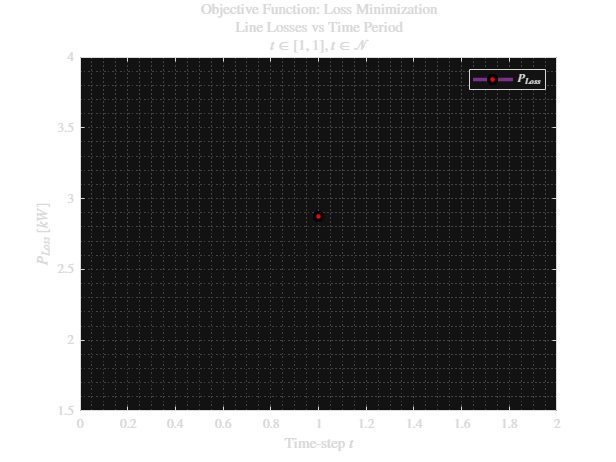

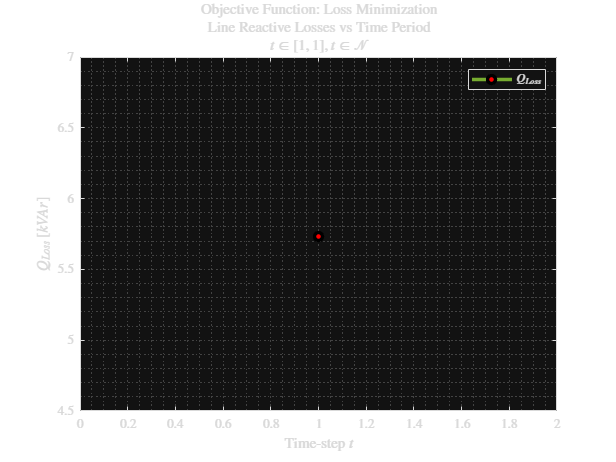

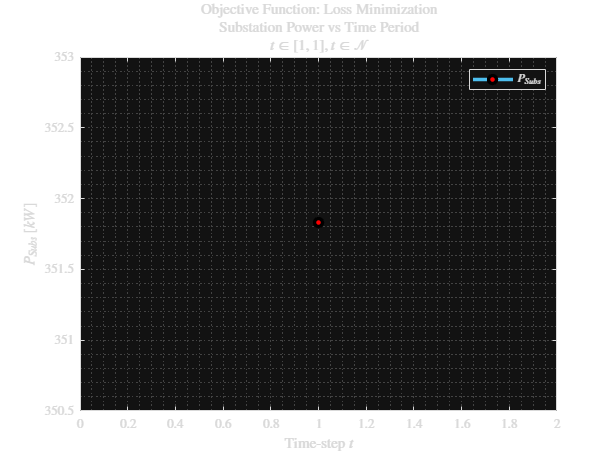

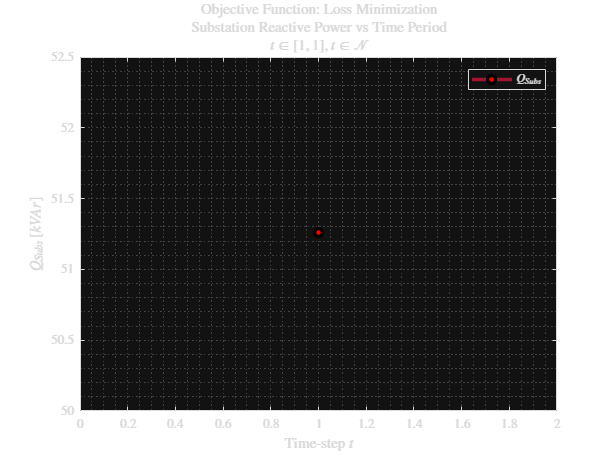

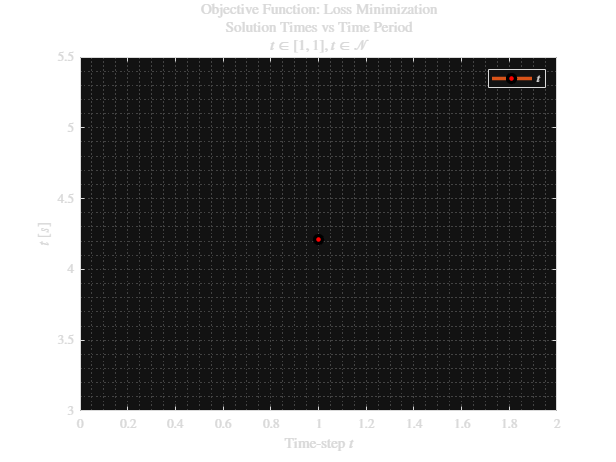

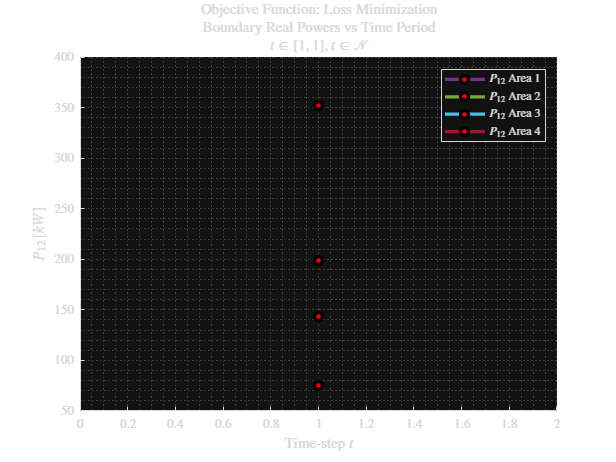

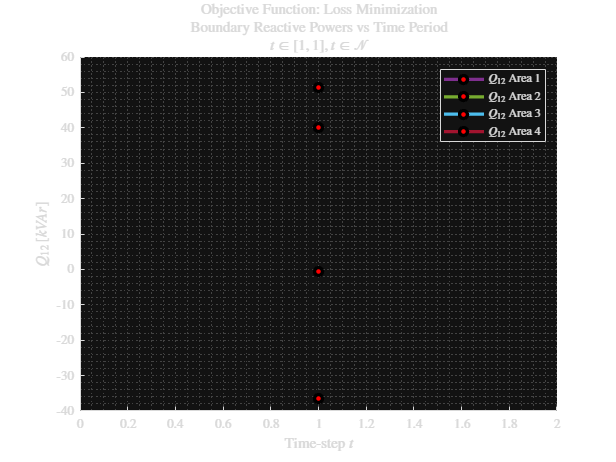

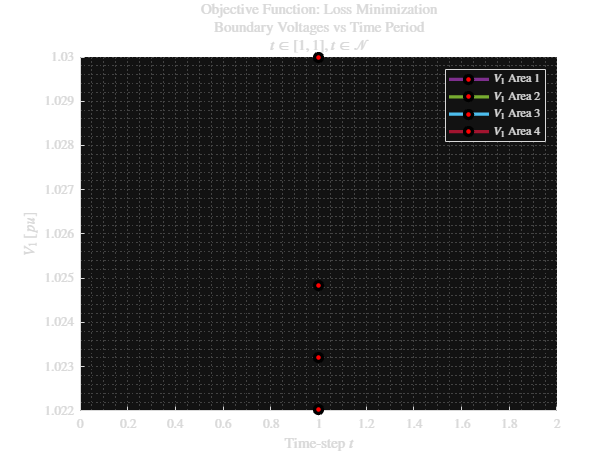

plotSimulationResults(results, 'verbose', true);